## 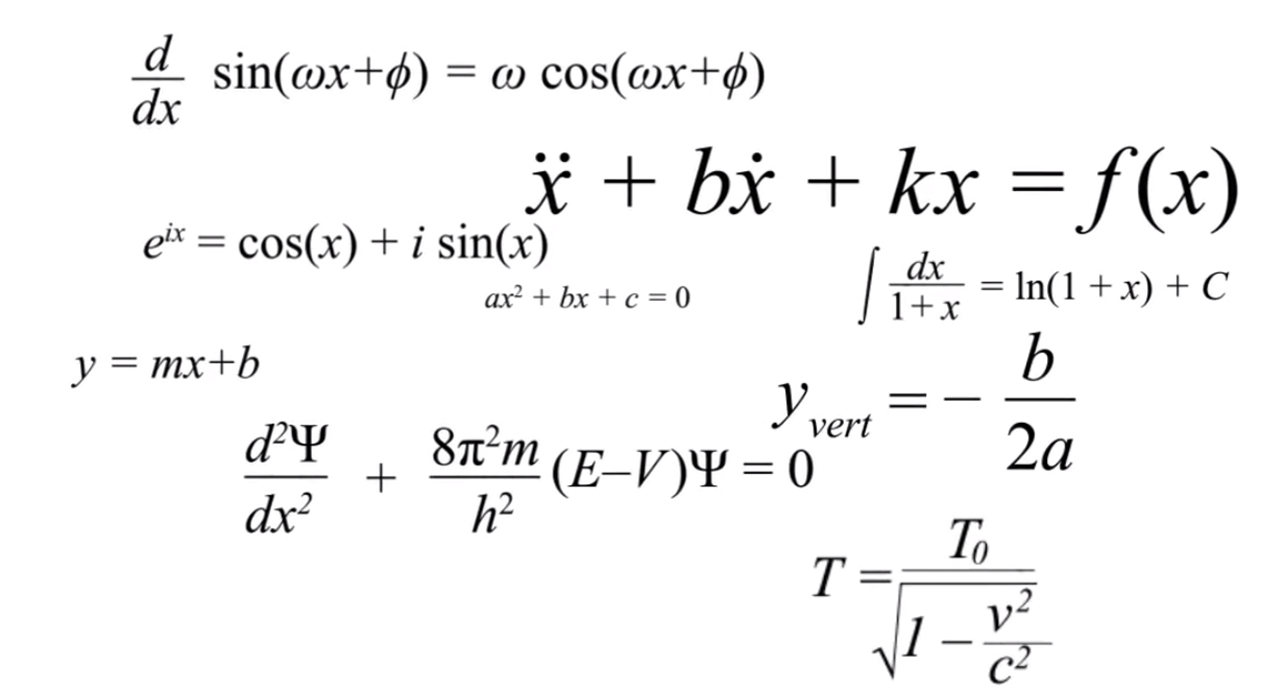

# **Lenguaje Simbólico**

## **Introducción**

Estamos acostumbrados a utilizar expresiones matemáticas simbólicas, aquellas que representan funciones y variables sin necesidad de adquirir ningún valor numérico. 

Existe software especializado en el trabajo con expresiones simbólicas, destacan por ejemplo Mathematica o Wolfram Alpha. MATLAB, aunque normalmente trabaja con variables que tienen un valor numérico también incorpora una librería con múltiples funciones para trabajar con estas expresiones simbólicas. En este tema veremos algunas de estas funciones. 

## **Construcción de variables y funciones simbólicas**

Para definir variables simbólicas utilizaremos la función *syms. *Cualquier variable que se defina a partir de una variable simbólica se convierte automáticamente en simbólica. La función syms sin argumentos muestra el listado de variables y expresiones simbólicas. 

syms x y;  %creamos las variables simbólicas x e y, con las que ya podemos operar de
                         %forma simbólica
syms x, f=x^2+2*x+1 %creamos la variable simbólica x y la expresión simbólica f

$$f = x^{2}+2\,x+1$$

syms

Your symbolic variables are:

f  x  y                                                                                                                                



Podemos cambiar el comportamiento de las variables entre simbólicas y numéricas con las funciones *sym* y *double*.

clear x y f
syms
a=pi                    % a es una variable numérica

a = 3.1416

b=sym(a)                % b es una variable simbólica

$$b = \pi$$

c=a/2;                  % c se convierte automáticamente a simbólica
d=double(c)             % d es la conversión a numérica de la variable simbólica c

d = 1.5708

Podemos realizar diversas operaciones con las expresiones simbólicas. 

La función *subs* permite sustituir variables simbólicas por otra variable simbólica o por su valor. 

clear all
syms x z t;
f=x^3+1,g=z^2+1

$$f = x^{3}+1$$

$$g = z^{2}+1$$

f2=subs(f,x,t)

$$f2 = t^{3}+1$$

f3=subs(f,x,3)

$$f3 = 28$$

g1=subs(g,z,1)

$$g1 = 2$$

Podemos asignar valores a las variables simbólicas y utilizar la función *subs* para evaluar las expresiones simbólicas.

z=1:3

z =      1     2     3


valores_sym=subs(g)                 % El resultado es un valor simbólico

$$valores\_sym = \left(\begin{array}{ccc} 2 & 5 & 10 \end{array}\right)$$

valores_num=double(valores_sym)     % Convertimos a valor numérico

valores_num =      2     5    10


syms

Your symbolic variables are:

f            f2           f3           g            g1           t            valores_sym  x                                      



Podemos operar con las expresiones simbólicas como lo haríamos normalmente.

clear all
syms x y z, f=x^2+3*y-z/2, g=-3*x^2+y/4+z

$$f = x^{2}+3\,y-\frac{z}{2}$$

$$g = -3\,x^{2}+\frac{y}{4}+z$$

f2=f+g

$$f2 = -2\,x^{2}+\frac{13\,y}{4}+\frac{z}{2}$$

f3=f/g

$$f3 = \frac{x^{2}+3\,y-\frac{z}{2}}{-3\,x^{2}+\frac{y}{4}+z}$$

solve(f2)

$$ans = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{13\,y+2\,z}}{4}\\ \frac{\sqrt{2}\,\sqrt{13\,y+2\,z}}{4} \end{array}\right)$$

### Ejercicio 1

Define f = ax^2 + bx + c. Sustituye x por t. Para a=2, b=1, c=0, obtener el valor de f en dos caso: (f_a) cuando t=2 y (f_b) cuando t=[1:4].


clc;clear;
syms a b c t
funcion = a*t^2 +b*t +c 

$$funcion = a\,t^{2}+b\,t+c$$


solucion_1 = subs(funcion, [a b c t],[2 1 0 2])

$$solucion\_1 = 10$$

for i=1:4
    solucion_2(:,i) = subs(funcion, [a b c t],[2 1 0 i])
end

$$solucion\_2 = 3$$

$$solucion\_2 = \left(\begin{array}{cc} 3 & 10 \end{array}\right)$$

$$solucion\_2 = \left(\begin{array}{ccc} 3 & 10 & 21 \end{array}\right)$$

$$solucion\_2 = \left(\begin{array}{cccc} 3 & 10 & 21 & 36 \end{array}\right)$$

## Simplificación de expresiones simbólicas

Existen diversas funciones que nos permiten simplificar y expandir las expresiones simbólicas con el objetivo de operar de forma más conveniente con ellas. 

La función *simplify *permite simplificar una expresión simbólica compleja. La función expand también permite la simplicación de las funciones mediante la búsqueda de expresiones alternativas. Existen otras funciones como *combine* y *factor* que también resultan de interés para la simplicación de expresiones simbólicas. 

clear all
syms x, f=exp(-1i*x)+exp(1i*x)

$$f = {\mathrm{e}}^{-x\,\mathrm{i}}+{\mathrm{e}}^{x\,\mathrm{i}}$$

simplify(f)

$$ans = 2\,\cos\left(x\right)$$

g=log(x)-log(2*x)               % log(a)-log(b)=log(a/b)

$$g = \log\left(x\right)-\log\left(2\,x\right)$$

simplify(g)                     % simplify deja la expresión como estaba

$$ans = \log\left(x\right)-\log\left(2\,x\right)$$

expand(g)

$$ans = -\log\left(2\right)$$


h1=sin(2*x)

$$h1 = \sin\left(2\,x\right)$$

expand(h1)

$$ans = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

### Ejercicio 2

Define la matriz M:


$$\left\lbrack \begin{array}{cc}
\cos \left(2\theta \right) & \sin \left(\theta \right)\\
\sin \left(\theta \right) & \sin^2 \left(\theta \right)
\end{array}\right\rbrack$$


*Puedes usar cualquier nombre para definir la variable simbólica $\theta$. 

Calcula el determinante y simplificalo. A continuación, calcula los autovalores para un valor $\theta =\frac{\pi }{2}$ y transformalo en una variable numérica. 

syms theta

M = [cos(2*theta) sin(theta); sin(theta) sin(theta)^2]

$$M = \left(\begin{array}{cc} \cos\left(2\,\theta \right) & \sin\left(\theta \right)\\ \sin\left(\theta \right) & {\sin\left(\theta \right)}^{2} \end{array}\right)$$


Determinante = det(M)

$$Determinante = \cos\left(2\,\theta \right)\,{\sin\left(\theta \right)}^{2}-{\sin\left(\theta \right)}^{2}$$


Determinante_simplificado = simplify(Determinante)

$$Determinante\_simplificado = -2\,{\sin\left(\theta \right)}^{4}$$


Autovalores_simbolicos = eig(M)

$$Autovalores\_simbolicos = \begin{array}{l} \left(\begin{array}{c} \frac{\cos\left(2\,\theta \right)}{2}+\frac{{\sin\left(\theta \right)}^{2}}{2}-\sigma_{1}\\ \frac{\cos\left(2\,\theta \right)}{2}+\frac{{\sin\left(\theta \right)}^{2}}{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{4\,{\cos\left(\theta \right)}^{4}-4\,{\cos\left(\theta \right)}^{2}\,{\sin\left(\theta \right)}^{2}-4\,{\cos\left(\theta \right)}^{2}+{\sin\left(\theta \right)}^{4}+6\,{\sin\left(\theta \right)}^{2}+1}}{2} \end{array}$$


Autovalores_numericos = double(subs(Autovalores_simbolicos, [theta],[pi/2]))

Autovalores_numericos =    -1.4142
    1.4142


## Diferenciación e integración

A continuación se resumen las funciones que permiten derivar e integrar las expresiones simbólicas.

**FUNCIÓN                                             SALIDA**

diff(f)                                                      Deriva f respecto de la variable simbólica preferente       

diff(f,u)                                                   Deriva f respecto a la variable u

int(f)                                                       Calcula una primitiva de f respecto de la variable simbólica preferente

int(f,s)                                                     Calcula una primitiva de f respecto de la variable simbólica s

int(f,a,b)                                                  Calcula la integral definida de f respecto de la variable simbólica preferente

int(f,s,a,b)                                               Calcula la integral definida de f respecto de la variable s

Por defecto, la variable preferente en una expresión simbólica es la letra ***x***. Si ésta no interviene en la expresión, se toma la letra minúscula más próxima a ella según el orden alfabético y que no sea ni la i ni la j. En caso de que haya dos (una anterior y otra posterior), se considera variable preferente el caracterposterior.

clear all
syms x t
f=x^2

$$f = x^{2}$$

derivada_f=diff(f)

$$derivada\_f = 2\,x$$

integral_f=int(f)

$$integral\_f = \frac{x^{3}}{3}$$


g=x^2+2*t^3

$$g = 2\,t^{3}+x^{2}$$

derivada_g=diff(g,t)

$$derivada\_g = 6\,t^{2}$$

integral_g=int(g,t)

$$integral\_g = \frac{t^{4}}{2}+t\,x^{2}$$

int_def_g=int(g,t,0,3)

$$int\_def\_g = 3\,x^{2}+\frac{81}{2}$$

### Ejercicio 3

Para una función del tipo g = y^2+ cos(z), calcula$\frac{d}{\mathrm{d}y}\left(\int_0^{\pi } g\;\textrm{dz}\right)$

clc;clear;
syms y z
funcion_g = y^2 +cos(z)

$$funcion\_g = y^{2}+\cos\left(z\right)$$


Integral_definida_z = int(funcion_g,z,0,pi)

$$Integral\_definida\_z = \pi \,y^{2}$$


Derivada_y = diff(Integral_definida_z,y)

$$Derivada\_y = 2\,\pi \,y$$


%Podemos hacer todo junto en lugar de tener una variable intermedia, pero a
%cambio nuestro código costará más de leer.

Derivada_de_integral = diff(int(funcion_g,z,0,pi),y)

$$Derivada\_de\_integral = 2\,\pi \,y$$

# **Importar datos**

## Introducción

En Matlab se pueden crear variables a partir de multiples tipos de datos. Un resumen se puede observar en la tabla [https://es.mathworks.com/help/matlab/import_export/supported-file-formats.html](https://es.mathworks.com/help/matlab/import_export/supported-file-formats.html)

## Importar desde fichero de texto o hoja de cálculo

Se pueden importar los datos en formato matriz, tabla, cell array u obtener una sola variable a través de las funciones: *readmatrix*, *readtable*, *readcell* o *readvars*

opts = detectImportOptions('outages.csv');
preview('outages.csv', opts)

ans = 8×6 table
       Region           OutageTime        Loss     Customers     RestorationTime            Cause       
    _____________    ________________    ______    __________    ________________    ___________________

    {'SouthWest'}    2002-02-01 12:18    458.98    1.8202e+06    2002-02-07 16:50    {'winter storm'   }
    {'SouthEast'}    2003-01-23 00:49    530.14    2.1204e+05                 NaT    {'winter storm'   }
    {'SouthEast'}    2003-02-07 21:15     289.4    1.4294e+05    2003-02-17 08:14    {'winter storm'   }
    {'West'     }    2004-04-06 05:44    434.81    3.4037e+05    2004-04-06 06:10    {'equipment fault'}
    {'MidWest'  }    2002-03-16 06:18    186.44    2.1275e+05    2002-03-18 23:23    {'severe storm'   }
    {'West'     }    2003-06-18 02:49       


t = readtable('outages.csv');
c = readcell('outages.csv');
c(4,3)

ans = 1×1 cell array
    {[289.4035]}


[Area Tiempo] = readvars('outages.csv');
whos Area Tiempo

  Name           Size             Bytes  Class       Attributes

  Area        1468x1             174988  cell                  
  Tiempo      1468x1              23520  datetime              



Al importar una matriz sólo se importan de manera automática los valores numéricos.

readmatrix('outages.csv')

ans = 	1.0e+06 *

       NaN       NaN    0.0005    1.8202       NaN       NaN
       NaN       NaN    0.0005    0.2120       NaN       NaN
       NaN       NaN    0.0003    0.1429       NaN       NaN
       NaN       NaN    0.0004    0.3404       NaN       NaN
       NaN       NaN    0.0002    0.2128       NaN       NaN
       NaN       NaN         0         0       NaN       NaN
       NaN       NaN    0.0002       NaN       NaN       NaN
       NaN       NaN    0.0003       NaN       NaN       NaN
       NaN       NaN    0.0002    0.0494       NaN       NaN
       NaN       NaN    0.0003    0.0661       NaN       NaN



opts = detectImportOptions('airlinesmall_subset.xlsx');
opts.Sheet = '2007';
opts.SelectedVariableNames = 1:5; 
opts.DataRange = '2:11';
M = readmatrix('airlinesmall_subset.xlsx',opts)

M =         2007           1           2           2         711
        2007           1           3           3         652
        2007           1           4           4        1116
        2007           1           5           5         825
        2007           1           7           7        1411
        2007           1           8           1        1935
        2007           1           9           2        2005
        2007           1          11           4        1525
        2007           1          12           5        1133
        2007           1          13           6         922


### Ejercicio 4

El fichero 'tsunamis.xlsx' contiene un listado de tsunamis ocurridos desde 1950. Analiza la infomación del fichero y representa, por media de una nube de puntos, los lugares (latitud, longitud) donde sucedieron los eventos.

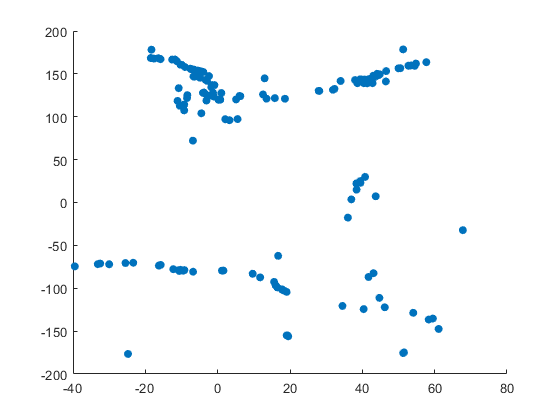

clc;clear;close all;

[Latitude ,Longitude] = readvars('tsunamis.xlsx');

scatter(Latitude,Longitude,'filled')

## Importar imágenes

Para importar imagenes se admiten multiples formatos pero hay que tener en cuenta que el formato de fichero que estamos importando. 

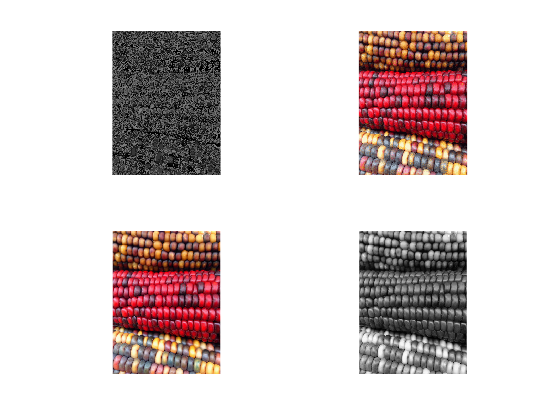

[corn_indexed,map] = imread('corn.tif',1);
corn_rgb = imread('corn.tif',2);
corn_gray = imread('corn.tif',3);
subplot (2,2,1)
imshow(corn_indexed)
subplot (2,2,2)
imshow(corn_indexed, map)
subplot (2,2,3)
imshow(corn_rgb)
subplot (2,2,4)
imshow(corn_gray)

## Importdata

La función *importdata* permite importar múltiples tipos de datos. Crea un fichero 'file1.txt' con la siguiente información:

`Day1  Day2  Day3  Day4  Day5  Day6  Day7`

`95.01 76.21 61.54 40.57  5.79 20.28  1.53`

`23.11 45.65 79.19 93.55 35.29 19.87 74.68`

`60.68  1.85 92.18 91.69 81.32 60.38 44.51`

`48.60 82.14 73.82 41.03  0.99 27.22 93.18`

`89.13 44.47 17.63 89.36 13.89 19.88 46.60`

% A = importdata('ngc6543a.jpg');
% image(A);
% 
% filename = 'file1.txt';
% delimiterIn = ' ';
% headerlinesIn = 1;
% A1 = importdata(filename,delimiterIn,headerlinesIn);
% 
% A2 = importdata('-pastespecial'); %Crea el fichero a partir de lo guardado en el portapapeles
% 
% for k = [3 5]
%    disp(A1.colheaders{1, k})
%    disp(A1.data(:, k))
%    disp(' ')
% end


### Ejercicio 5

La figura '`peppers.png`' contiene un bodegón de pimientos en formato RGB. Importa la figura y crea una segunda matriz cuyo tamaño sea los pixeles de la figura. Es decir si el tamaño de la matriz donde se ha importado la figura es 400x400x3, la segunda matriz debe tener un tamaño de 400x400. 

Esta segunda matriz tomara el valor 1 si el valor del color rojo (posiciones M( : ,: , 1)) es mayor de 200 (posibilidad de presencia de pimiento rojo) y 0 en el resto de casos. 

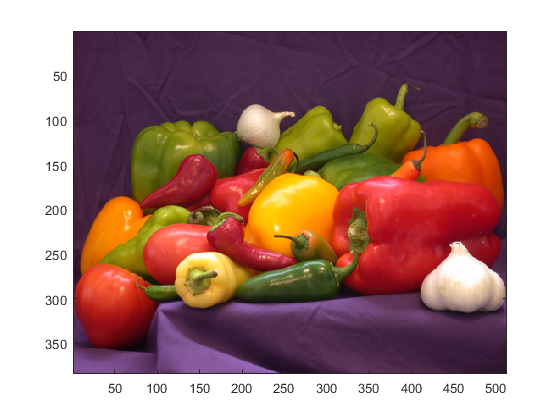

clc;clear;close all

Bodegon = importdata('peppers.png');
image(Bodegon);


Matriz_comprobacion = zeros(size(Bodegon,1), size(Bodegon,2));

Matriz_comprobacion = Bodegon(:,:,1)>200

Matriz_comprobacion = 384×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

% Voy a añadir un par de lineas para confirmar que he tratado todos los
% pixeles de la matriz.

% Cuento el numero total de unos y ceros.
Numero_de_unos  = sum(sum(Matriz_comprobacion == 1))
Numero_de_ceros = sum(sum(Matriz_comprobacion == 0))
% Cuento el numero de pixeles de la imagen
Numero_de_pixeles = size(Bodegon,1)*size(Bodegon,2)

% Si la siguiente sentencia logica da uno, es que coinciden los pixeles.
Comprobacion_de_pixeles = Numero_de_pixeles == (Numero_de_unos+Numero_de_ceros)

